# Sample Homework 2

Math 3607, Autumn 2021

Tae Eun Kim.3562

## Problem 1. Training plan

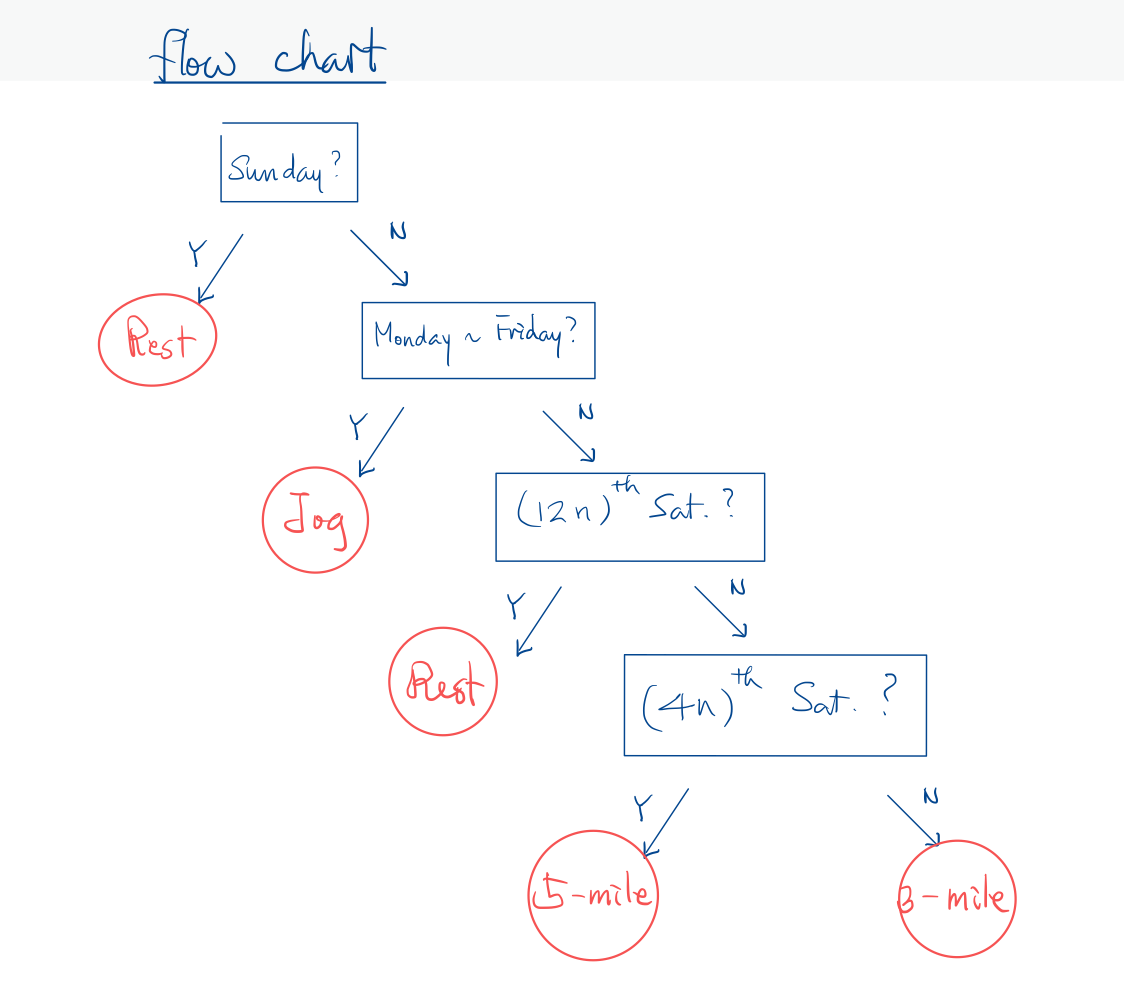

d = randi([1,365], 1, 1);
if mod(d,7)==0
    disp('Rest')
elseif mod(d,7)<=5
    disp('Jog')
elseif mod(d,7*12)==7*12-1
    disp('Rest')
elseif mod(d,7*4)==7*4-1
    disp('5-mile')
else
    disp('3-mile')
end

Rest


## Problem 2. Angle finder

help atan2

 atan2  Four quadrant inverse tangent.
    atan2(Y,X) is the four quadrant arctangent of the elements of X and Y
    such that -pi <= atan2(Y,X) <= pi. X and Y must have compatible sizes.
    In the simplest cases, they can be the same size or one can be a
    scalar. Two inputs have compatible sizes if, for every dimension, the
    dimension sizes of the inputs are either the same or one of them is 1.
 
    See also atan, atan2d.

    Documentation for atan2
    Other functions named atan2




x = 1; y = 2; z = 3;
myConversion

rho =      1

phi =            1.5707963267949

theta =           4.71238898038469

x = 2; y = 0; z = 1798;
myConversion

rho =      1

phi =            1.5707963267949

theta =           4.71238898038469

## Problem 3. Guess-the-number

type guess.m

lBound = input('lower bound: ');
uBound = input('upper bound: ');
theNum = randi([lBound, uBound]);
while true
    numGuess = input('What is your guess? ');
    if numGuess > theNum
        disp('Your guess is too high. Try again.')
    elseif numGuess < theNum
        disp('Your guess is too low. Try again.')
    else
        disp('Congratulations!')
        break;
    end
end


## Problem 4. Biased Dice

#### Simulating single roll

#### Simulating rolls of two dice until sum=7; Repeat the prev. sim. 10 times

for i = 1:10
    nrRolls = 0;
    sumRolls = 0;
    while sumRolls ~= 7
        % simulation
        myRoll; roll1 = roll;
        myRoll; roll2 = roll;
        % update
        nrRolls = nrRolls + 1;
        sumRolls = roll1 + roll2;
    end
    fprintf('Simulation %2d done in %2d roll(s).\n', i, nrRolls)
end

Simulation  1 done in  5 roll(s).
Simulation  2 done in  1 roll(s).
Simulation  3 done in  1 roll(s).
Simulation  4 done in  6 roll(s).
Simulation  5 done in 13 roll(s).
Simulation  6 done in  5 roll(s).
Simulation  7 done in  1 roll(s).
Simulation  8 done in  5 roll(s).
Simulation  9 done in  4 roll(s).
Simulation 10 done in  1 roll(s).


## Problem 5. Approximating $\pi$

We will work with $\mu_n$ only.

$U_n = \sum_{k=1}^n \frac{1}{k^4} \approx \frac{\pi^4}{90}$, $\mu_n = \sqrt[4]{90 U_n}$

% Form the sum U_n using a for-loop.
for n = 100:100:1000
    if n == 100
        fprintf(' %4s %10s\n', 'n', 'error')
        fprintf('----------------')
    end
    U_n = 0;
    for k = 1:n
        U_n = U_n + 1/k^4;
    end
    mu_n = nthroot(90*U_n, 4);
    fprintf(' %4d %10.2e\n', n, abs(pi - mu_n))
end

    n      error


----------------

  100   2.38e-07
  200   3.00e-08
  300   8.91e-09
  400   3.77e-09
  500   1.93e-09
  600   1.12e-09
  700   7.04e-10
  800   4.72e-10
  900   3.31e-10
 1000   2.42e-10


% Form the sum U_n using a for-loop.
errTol = 1e-121;
err = Inf;
n = 0;

while err > errTol
    n = n + 100;
    U_n = 0;
    for k = 1:n
        U_n = U_n + 1/k^4;
    end
    mu_n = nthroot(90*U_n, 4);
    err = abs(pi - mu_n);
    fprintf(' %4d %10.2e\n', n, err)
end

  100   2.38e-07
  200   3.00e-08
  300   8.91e-09
  400   3.77e-09
  500   1.93e-09
  600   1.12e-09
  700   7.04e-10
  800   4.72e-10
  900   3.31e-10
 1000   2.42e-10
 1100   1.81e-10
 1200   1.40e-10
 1300   1.10e-10
 1400   8.81e-11
 1500   7.16e-11
 1600   5.90e-11
 1700   4.92e-11
 1800   4.14e-11
 1900   3.52e-11
 2000   3.02e-11
 2100   2.61e-11
 2200   2.27e-11
 2300   1.99e-11
 2400   1.75e-11
 2500   1.55e-11
 2600   1.38e-11
 2700   1.23e-11
 2800   1.10e-11
 2900   9.91e-12
 3000   8.95e-12
 3100   8.11e-12
 3200   7.38e-12
 3300   6.73e-12
 3400   6.15e-12
 3500   5.64e-12
 3600   5.18e-12
 3700   4.77e-12
 3800   4.40e-12
 3900   4.07e-12
 4000   3.78e-12
 4100   3.51e-12
 4200   3.26e-12
 4300   3.04e-12
 4400   2.84e-12
 4500   2.65e-12
 4600   2.48e-12
 4700   2.33e-12
 4800   2.18e-12
 4900   2.05e-12
 5000   1.93e-12
 5100   1.82e-12
 5200   1.72e-12
 5300   1.62e-12
 5400   1.53e-12
 5500   1.45e-12
 5600   1.37e-12
 5700   1.30e-12
 5800   1.24e-12
 5900   1.18e-